# Making 3D matrix

- Each cell has 2D matrix. Overall, there are 84 cell for each note respectevily

- Each row of matrix represents separate spectrum

z - хранит звуковой сигнал в массиве

Ns - кол-во отчетов при вырезке

Nn - кол-во нот

clear all
close all
path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav";
path1 = path + "\Sasha\Steinway Grand Piano 70.wav";
path2 = path + "\Sasha\Yamaha Grand Piano 70.wav";
[y, Fs] = audioread(path1);
z = y(:,1);
clear y

Константы

Nn = 84;
Ns = 1024;

Tab_F_1 = [65.41  69.3  73.42  77.78  82.41  87.31  92.5  98  103.83  110  116.54  123.47];
k = 2.^(0:6);

Tab_F = k' * Tab_F_1;
FlatTab_F = reshape(Tab_F.',1,[]);

Создаю объект Q, в котором будет сохранен 3Д объект

t_one = 2;                  % Одна нота длится 2 секунды
dt = 1/Fs;                  % Время между отчетами
t_min = Ns*dt;              % Время вырезки
N_row = floor(t_one/t_min); % Количество вырезок за 2 секунды


Q = zeros(Nn, N_row, Ns);

Заполняю объект

Первый цикл - выделяю сигнал одной ноты

Второй цикл - разделяю выдеенный сигнал на кол-во спектров

for i = 1:Nn
    
    N_sam_one = 2*Fs*t_one;      % Кол-во отчетов на 4 секунды (1нота и пауза)
    N1 = N_sam_one * (i-1) + 1;      % Сдвиг сигнала по нотам
    N2 = N1 + N_sam_one - 1;
    
    z1 = z(N1:N2);
    
    for j = 1:N_row
        
        N1 = Ns * (j-1) + 1;
        N2 = N1 + Ns - 1;
        
        z2 = z1(N1:N2);
        
        Spec = fft(z2);
        Q(i, j, :) = Spec;
        
    end
    
end

% save('Spectra_each_note.mat', 'Q');

Проверка объекта, посмотрю на некоторые спектры

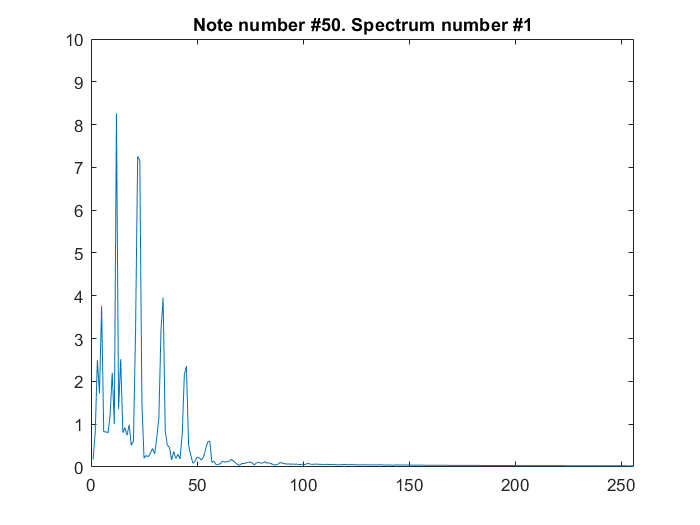

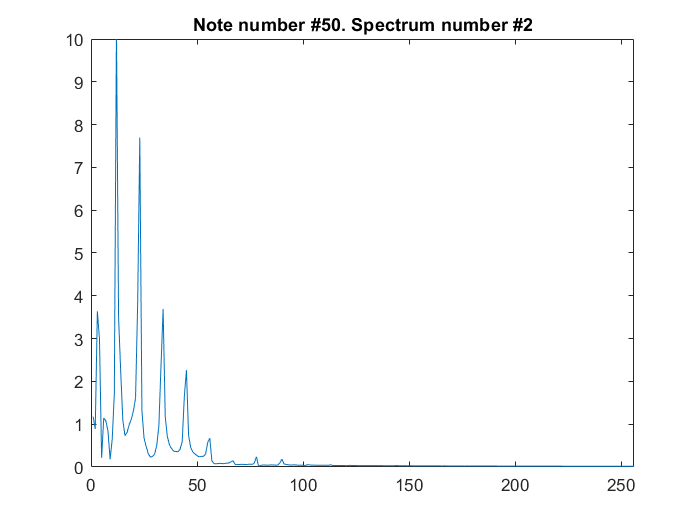

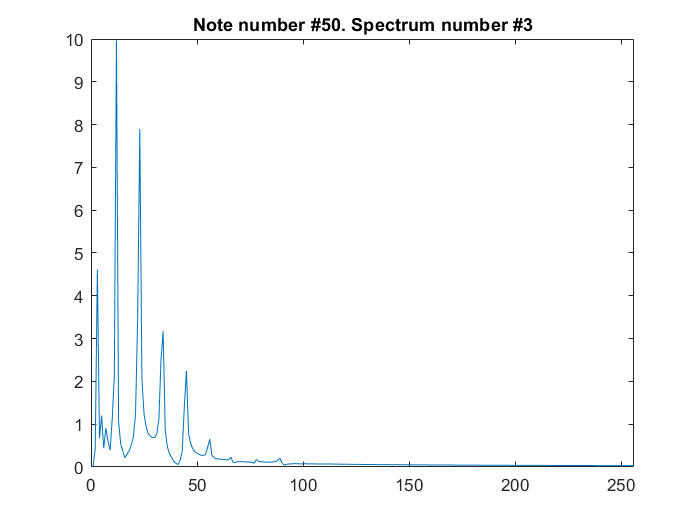

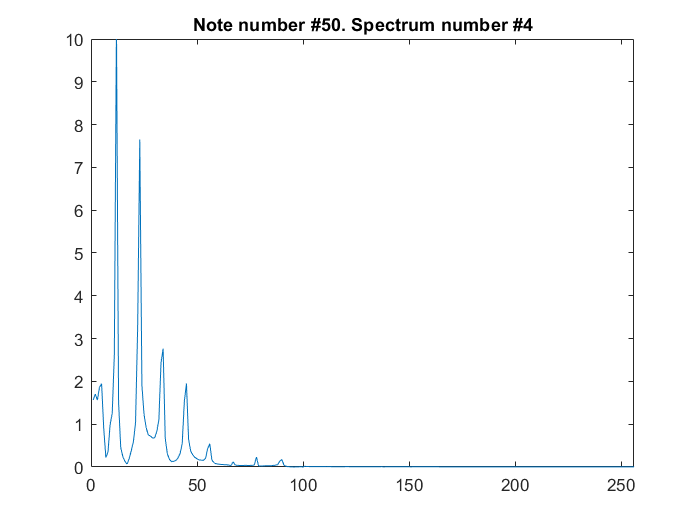

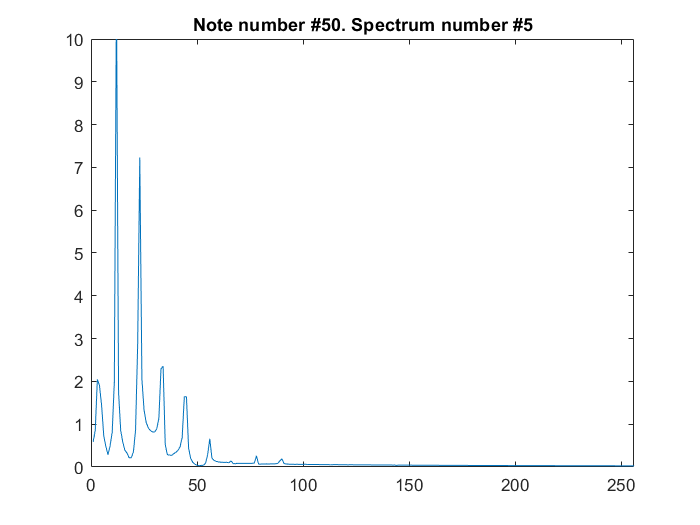

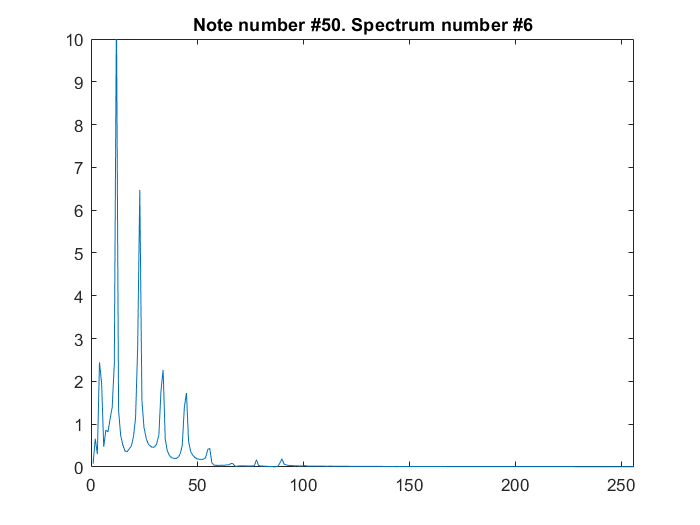

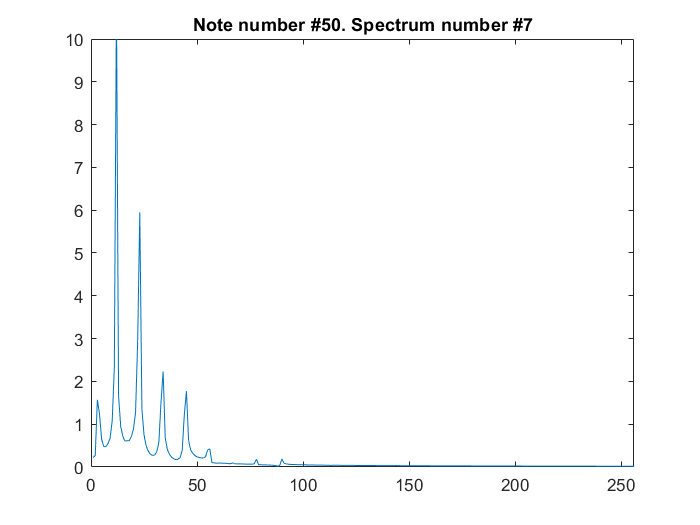

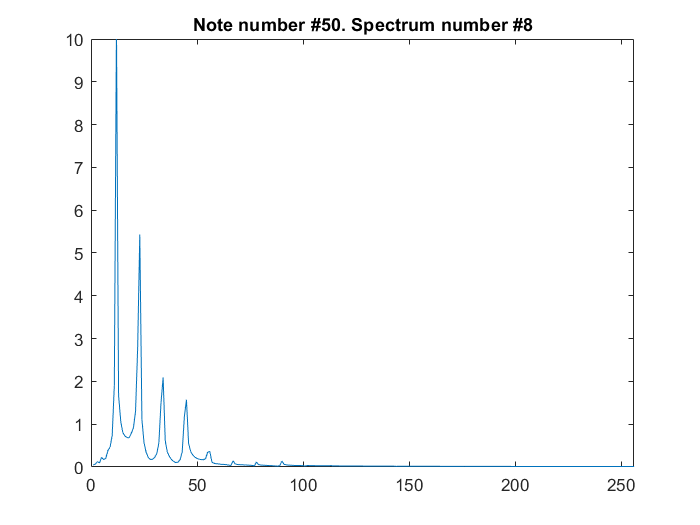

cnt = 1;
for i = 50:51
    
    for j = 1:N_row
        
        sig = Q(i, j, :);
        sig = squeeze(sig);    % Reduce dimentions 1x1x1024 --> 1024
        
        figure (cnt)
        plot(abs(sig))
        title("Note number #" + string(i) + '. Spectrum number #' + string(j))
        xlim([0 Ns/4])
        ylim([0 10])
        
        cnt = cnt+1;
    end
end